# Løsning på lortet

## Opgave 1

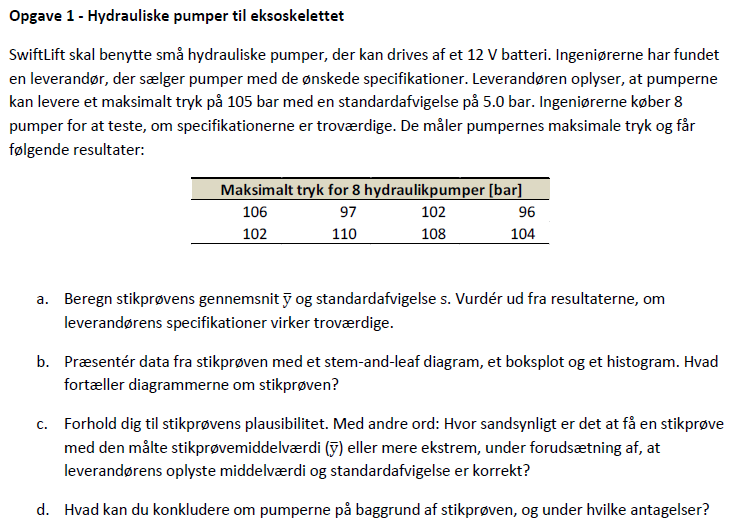

clc; clear all;

% Data indlæses
data = xlsread("Data_M4STI1_2018E (1).xlsx", 'A:A');

% Opgave a
D = sort(data)

D =     96
    97
   102
   102
   104
   106
   108
   110



n = length(D)       % Antal datapunkter

n = 8

mdl = mean(data)    % Stikprøvens middelværdi

mdl = 103.1250

stdafv = std(D)  % Populationsdata, derfor n-1

stdafv = 4.9407


afv = [mdl + stdafv; mdl - stdafv]

afv =   108.0657
   98.1843



max(D), min(D)

ans = 110

ans = 96


% Det ses at gennemsnittet +/- 1 standard afvigelse ligger indenfor rækkeviden min, max i datasættet

% Opgave b
D = data;
max(D)

ans = 110


stdafv = std(D)

stdafv = 4.9407


middel = mean(D)

middel = 103.1250

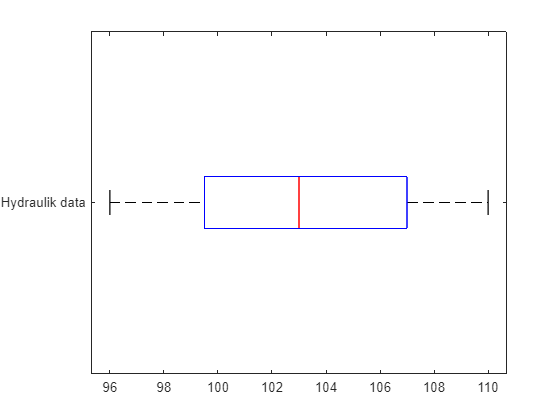


boxplot(D, 'Orientation','horizontal', 'Labels',{'Hydraulik data'})

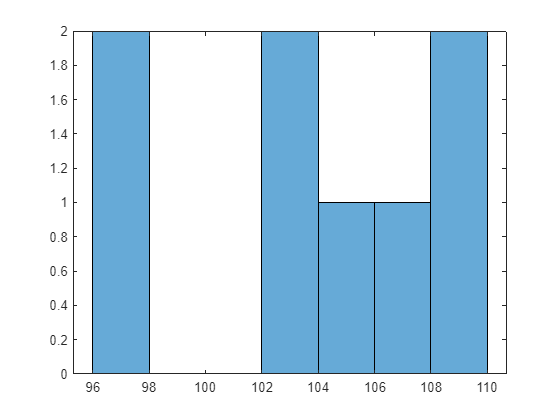

histogram(D, floor(min(D)):2:ceil(max(D)))


stemleafplot(D)

Unrecognized function or variable 'roundn'.

Error in stemleafplot (line 55)
v = roundn(v, -p);



prctile(D, [25,50,75])


% Opgave c
% Observerede værdier
mu_obs = 105;
std_obs = 5;

% Udregnede stikprøve værdier
Ybar = mdl;
std_obs = stdafv;

% Den centrale grænseværdisætning antages
Z = (Ybar - mu_obs)/(std_obs/sqrt(n))

% P(Z >= -1.0734)
ssh1 = normcdf(Z) % Ssh for at den er større end
ssh2 = 1 - normcdf(abs(Z))
ssh3 = ssh1 + ssh2

losningsforslag = 2*(1-normcdf(abs(Z)))



dist = makedist("Normal","mu",0,"sigma",1);
x = -3:0.01:3;

df = cdf(dist, x);
df1 = pdf(dist, x);

% Plot for forståelse
plot(x, df), xline(0), yline(0.5), grid(), xlabel("Standardafvigelser"), ylabel("Sandsynlighed")
hold on


x_less_Z = find(x < Z);
x_larger_Z = find(x > abs(Z));

% Komulativ fordelings plot
% mindre end Z
area(x(1, 1:length(x_less_Z)), df(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df(1, x_larger_Z(1):end));


hold off

% Ssh plot
plot(x, df1), xlabel("Standardafvigelser"), ylabel("Sandsynlighed"), grid()
hold on
% mindre end Z
area(x(1, 1:length(x_less_Z)), df1(1, 1:length(x_less_Z)));

% Større end Z
area(x(1, x_larger_Z(1):end), df1(1, x_larger_Z(1):end));
hold off

normplot(D)

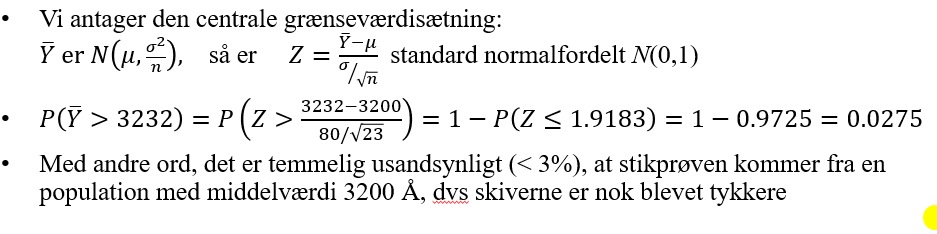

## Opgave 3

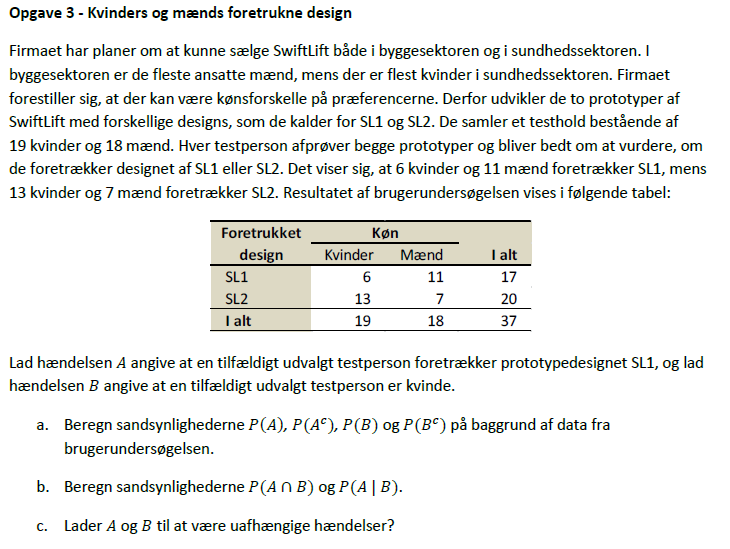

clc; clear all;

% SL1 data
sl1_k = 6
sl1_m = 11 
sl1_tot = sl1_k + sl1_m

% SL2 data
sl2_k = 13
sl2_m = 7 
sl2_tot = sl2_k + sl2_m

% Populations antal
n_tot = sl1_tot + sl2_tot

%---------------------------------------------%
%---------------- Udregninger ----------------%
%---------------------------------------------%

% Opgave a)
pA = sl1_tot/n_tot
pAc = 1-pA
pB = (sl1_k + sl2_k)/n_tot
pBc = 1 - pB

% Opgave b)
pA_og_B = sl1_k/n_tot
pA_hvis_B = sl1_k/sl1_tot

% Opgave c)
pA == pA_hvis_B
% Ved tjek om de 2 hændelser er ens, ses det at resultatet er 0, altså
% false, så de er afhængige

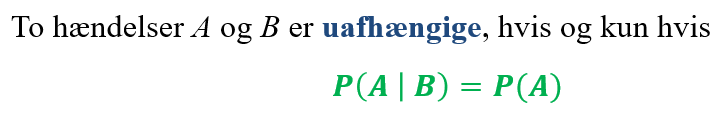

% Opgave e

%   kvinder mænd
SL1 = [6 11];
SL2 = [13 7];

SLtot = [SL1;SL2]

rowsum = sum(SLtot,2)
colsum = sum(SLtot,1)

total = sum(colsum)

rows = size(rowsum,1)
cols = size(colsum,2)

rowfreq = rowsum/total
colfreq = colsum/total

E = zeros(rows, cols);

for i = 1:rows
    for j = 1:cols
        E(i,j) = total*rowfreq(i)*colfreq(j);
    end
end

E

chi2 = 0;

for i = 1:rows
    for j = 1:cols
        chi2 = chi2 + (SLtot(i,j) - E(i,j))^2/E(i,j);
    end
end

chi2

sum(sum((SLtot - E).^2./E))

KontingensTabel(SLtot)









